clear; close all; clc;
BINS = 16;
items = 76;

J = cell(items,1);
R = cell(items,1);
G = cell(items,1);
B = cell(items,1);
I = cell(items,1);
r = cell(items,1);
g = cell(items,1);
rint = cell(items,1);
gint = cell(items,1);
colors = cell(items,1);
for k = 1:items
    filename = sprintf("cropped-images/%d.jpg", k);
    J{k} = double(imread(filename));
    % get RGB values for each image and store in a cell array
    R{k} = J{k}(:,:,1); 
    G{k} = J{k}(:,:,2);
    B{k} = J{k}(:,:,3);
    % get Intensity
    I{k} = R{k} + G{k} + B{k};
    I{k}((I{k}==0)) = 10000;
    % get NCC
    r{k} = R{k}./I{k}; g{k} = G{k}./I{k};
    rint{k} = round(r{k}*(BINS-1) + 1);
    gint{k} = round(g{k}*(BINS-1) + 1);
    % flatten NCC coordinates
    colors{k} = gint{k}(:) + (rint{k}(:)-1)*BINS; % subtract 1 for 0 coordinate
end

hist = zeros(BINS,BINS);
colors_t = vertcat(colors{:});
for row = 1:BINS
    for col = 1:(BINS-row+1)
        hist(row,col) = length(find(colors_t==(col + (row-1)*BINS)));
    end
end

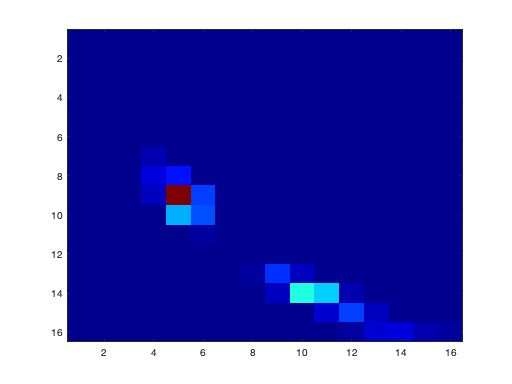

figure(1)
imagesc(imrotate(hist,90));
colormap(jet);